# 元胞自动机：森林火灾

**细胞自动机**（英语：Cellular automaton），又称**格状自动机**、**元胞自动机**，是一种[离散模型](https://zh.wikipedia.org/w/index.php?title=%E9%9B%A2%E6%95%A3%E6%A8%A1%E5%9E%8B&action=edit&redlink=1)，在[可算性理论](https://zh.wikipedia.org/w/index.php?title=%E5%8F%AF%E7%AE%97%E6%80%A7%E7%90%86%E8%AB%96&action=edit&redlink=1)、[数学](https://zh.wikipedia.org/wiki/%E6%95%B8%E5%AD%B8)及[理论生物学](https://zh.wikipedia.org/wiki/%E7%90%86%E8%AB%96%E7%94%9F%E7%89%A9%E5%AD%B8)都有相关研究。它是由无限个有规律、坚硬的方格组成，每格均处于一种有限[状态](https://zh.wikipedia.org/wiki/%E7%8B%80%E6%85%8B)。整个格网可以是任何有限维的。同时也是[离散](https://zh.wikipedia.org/wiki/%E9%9B%A2%E6%95%A3)的。每格于t时的态由t-1时的一集有限格（这集叫那格的邻域）的态决定。每一格的“邻居”都是已被固定的。（一格可以是自己的[邻居](https://zh.wikipedia.org/wiki/%E9%84%B0%E5%B1%85)。）每次演进时，每格均遵从同一规矩一齐演进。

　　一个最简单的二维概率元胞自动机是森林火灾模型, 森林火灾元胞自动机模型定义在正方网格上, 元胞有三种状态: 树 (未燃烧的树), 火 (正在燃烧的树) 和空状态. 某元胞下时刻状态由该时刻本身的状态和周围四个邻居的状态决定。

- **着火**: 若某元胞的状态为 “树”，且其最邻近的 4 个邻居元胞中有状态为 “火” 的元胞，则该元胞下时刻的状态由 “树” 变为 “火”，用以模拟火势的漫延. 对于邻居中没有 “火” 的情况，状态为 “树” 的元胞也会以一个低概率 f 变为 “火”，用以模拟闪电引起的火灾。

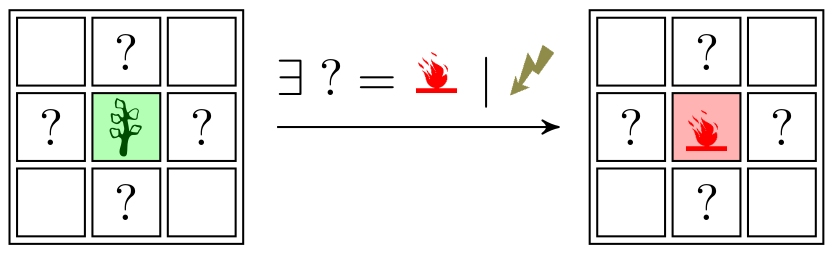

- **烧尽**: 状态为 “火” 的元胞，其状态在下一时刻将变成 “空”，用以模拟着火的树经过一定时间后被烧完。

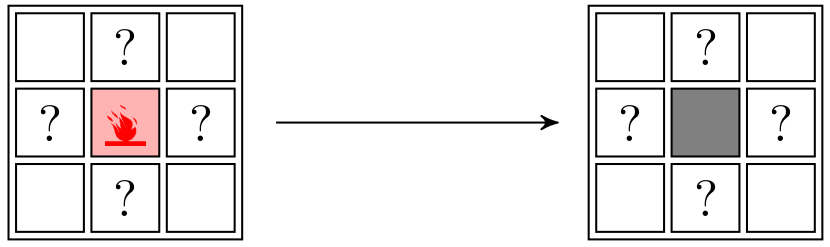

- **新生**: 状态为 “空” 的元胞，在下一时刻以一个低概率 p 变为 “树”，用以模拟新树的长出。

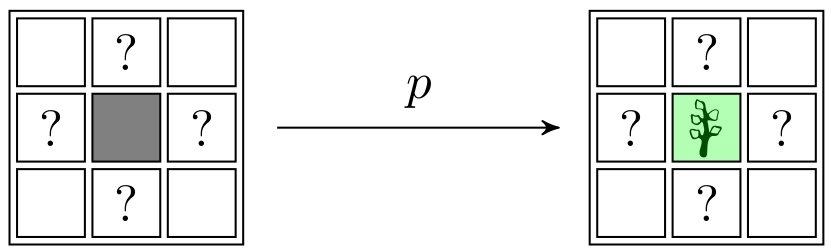

用0、1、2分别表示空、火、树三种状态，则森林可以用一个包含0、1、2三个整数的二维数组表示。

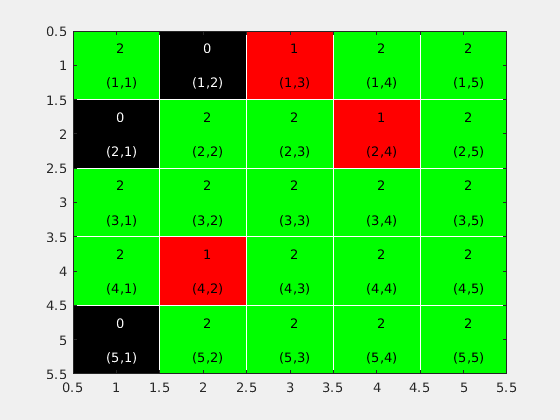

rng(3);
n = 5;
veg = rand(n);
veg(veg<0.1) = 1;
veg(veg<0.7) = 2;
veg(veg<1.0) = 0;
image(cat(3,(veg==1),(veg==2),zeros(n))); hold on
for i = 1:n
    for j = 1:n
        if veg(i,j)==0; c = 'w'; else c = 'k'; end
        text(j, i-0.25, int2str(veg(i,j)), 'color', c);
        text(j-0.125, i+0.25, ['(', int2str(i), ',' ,int2str(j),')'], 'color', c);
        plot(j+[-0.5 -0.5 +0.5 +0.5 -0.5], i+[-0.5 +0.5 +0.5 -0.5 -0.5], 'w')
    end
end
hold off

定义邻居并求邻居中状态为“火”的数量

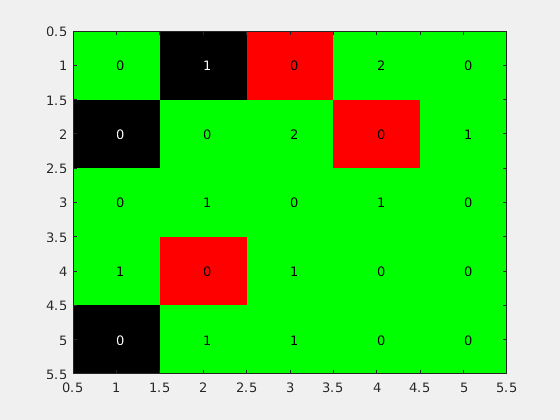

UL = [n 1:n-1]; 
DR = [2:n 1];

U = veg(UL,:);
D = veg(DR,:);
L = veg(:,UL);
R = veg(:,DR);

Sum =       (U==1) + ...
     (L==1)   +    (R==1) + ...
            (D==1);
        
image(cat(3,(veg==1),(veg==2),zeros(n))); hold on        
for i = 1:n
    for j = 1:n
        if veg(i,j)==0; c = 'w'; else c = 'k'; end
        text(j, i, int2str(Sum(i,j)), 'color', c);
    end
end
hold off

根据规则，更新元胞状态�状态

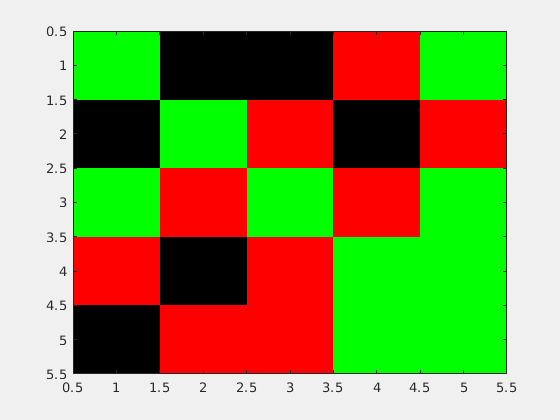

Plight = 5e-6; 
Pgrowth = 1e-2;

% 着火
Rule1 = 2*(veg==2) - ( (veg==2) & (Sum>0 | (rand(n,n)<Plight)) );

% 烧尽
Rule2 = 1*(veg==1) - 1*(veg==1);

% 新生
Rule3 = 2*((veg==0) & rand(n,n)<Pgrowth);

veg = Rule1 + Rule2 + Rule3;
image(cat(3,(veg==1),(veg==2),zeros(n)));

综合以上代码

figure('Visible','on')
n = 300;
Plight = 5e-6; 
Pgrowth = 1e-2;
UL = [n 1:n-1]; 
DR = [2:n 1];
veg=zeros(n,n);
imh = image(cat(3,(veg==1),(veg==2),zeros(n)));
for i=1:1000
    Sum =            (veg(UL,:)==1) + ...
        (veg(:,UL)==1)     +      (veg(:,DR)==1) + ...
                     (veg(DR,:)==1);

    veg = 2*(veg==2) - ...
          ( (veg==2) & (Sum>0 | (rand(n,n)<Plight)) ) + ...
          2*((veg==0) & rand(n,n)<Pgrowth) ;
     
    set(imh, 'cdata', cat(3,(veg==1),(veg==2),zeros(n)) )
    drawnow
end